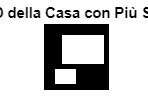

% Dimensioni della mappa
width = 50;
height = 50;

% Creiamo una matrice 2D di zeri
map = zeros(height, width);

% Disegniamo i muri esterni della casa
map(1, :) = 1; % Muro superiore
map(end, :) = 1; % Muro inferiore
map(:, 1) = 1; % Muro sinistro
map(:, end) = 1; % Muro destro

% Disegniamo alcuni muri interni
map(10:40, 20) = 0; % Muro verticale
map(20, 10:30) = 0; % Muro orizzontale
map(30:40, 35) = 0; % Altro muro verticale

% Rimuoviamo alcune parti dei muri per creare più spazi vuoti
map(10:30, 15:45) = 1; % Apertura nel muro orizzontale
map(35:45, 10:25) = 1; % Apertura nel muro verticale

% Mostriamo la mappa
figure;
imshow(map, 'InitialMagnification', 'fit');
colormap(gray);
title('Mappa 2D della Casa con Più Spazi Vuoti');